***Ejemplo spline cubico:***

Dada la nube de puntos, calcule los splines cubicos posibles.

X = [-8 -1 0 2 5 9 13 20] %Nodo

X =     -8    -1     0     2     5     9    13    20


Y = [7.5 6.8 -2.3 7.8 5.33 2.01 -2.56 -6.58] %Imagen

Y =     7.5000    6.8000   -2.3000    7.8000    5.3300    2.0100   -2.5600   -6.5800


***SPLINE CUBICO NATURAL***

S=csnatural(X,Y)

S =    -0.1063         0    5.1069    7.5000
    3.6453   -2.2315  -10.5137    6.8000
   -2.0794    8.7043   -4.0410   -2.3000
    0.5188   -3.7721    5.8234    7.8000
   -0.1012    0.8974   -2.8007    5.3300
    0.0376   -0.3167   -0.4781    2.0100
   -0.0064    0.1351   -1.2046   -2.5600


S es el spline cubico natural empezando en S0 y terminando en Sn 

(Primero de arriba a abajo)

Tambien, hay que destacar que los componentes de la amtriz de S van organizados del mayor al menor grado del polinomio. (x^3, luego x^2, luego x y finalmente constante)

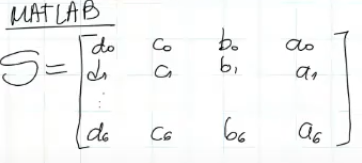

Para evaluar los resultados de todo spline cubico se procede de la siguiente manera:

Suponga que desea evaluar  11.8 

Si nos fijamos, 11.8 en el spline cubico pertence al tramo de S_6(x)  (esto porque el punto se encuentra en el tramo s6 de los nodos del spline) por tanto, para evaluarlo en matlab necesitamos:

polyval(Tramo_spline, [El valor que se quiere evaluar-nodo de la fila])

**En este caso**

S(6,:) %fila 6, y con los dos ptos le digo que coja

ans =     0.0376   -0.3167   -0.4781    2.0100


%todas las columnas
polyval(S(6,:),11.8-9)

ans = -0.9851

**Grafiquemos**

GraficaCercha(X,Y,S)
hold on
valor_aproximado = polyval(S(6,:),11.8-9)

valor_aproximado = -0.9851

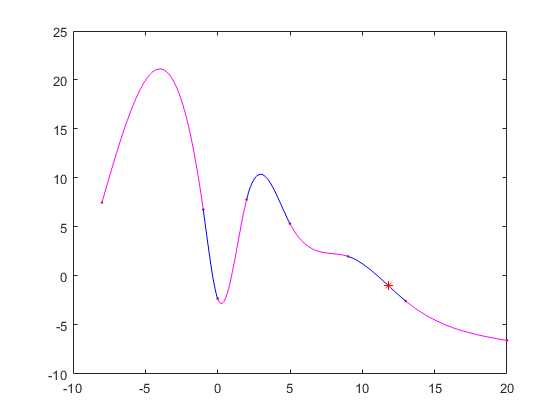

plot(11.8,valor_aproximado,"*r") %Efectivamente el pto esta sobre el spline

***SPLINE CUBICO SUJETO (PRIMERAS DERIVADAS)***

%S = csfit (X, Y, dx0, dxn) dx0 es derivada en x0 y en xn

S = csfit (X, Y, 2, -3)

S =    -0.1650    0.8550    2.0000    7.5000
    3.7948   -2.6099  -10.2848    6.8000
   -2.0945    8.7743   -4.1204   -2.3000
    0.5237   -3.7930    5.8423    7.8000
   -0.1085    0.9204   -2.7756    5.3300
    0.0627   -0.3815   -0.6202    2.0100
   -0.0513    0.3713   -0.6610   -2.5600


***SPLINE CONOCIDO (SGDA DERIVADA EXTREMOS)***

%S=csconocido(X,Y,a,b) a sda derivada xo y xn
S=csconocido(X,Y,a,b)

$$ans = \left(\begin{array}{c} 16\,c_{1}+c_{2}\\ c_{1}+6\,c_{2}+2\,c_{3}\\ 2\,c_{2}+10\,c_{3}+3\,c_{4}\\ 3\,c_{3}+14\,c_{4}+4\,c_{5}\\ 4\,c_{4}+16\,c_{5}+4\,c_{6}\\ 4\,c_{5}+22\,c_{6} \end{array}\right)$$

***SPLINE CONSTANTE (TERMINACION PARABOLICA)***

S=csconstante(X,Y)

***SPLINE EXTRAPOLADO***

S=csextrapolado(X,Y)

OJO CON LAS COMBINACIONES DE EXTRAPOLADO Y TERMINACION PARABOLICA POR EJEMPLO